# Dimensionality Reduction by Snapshot LSUN

## Preparation

clc, clear
close all

## Loading input image

Datasetfolder ='./Experience1/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(1).name));
u = single(data.u);

if canUseGPU
    disp("Use GPU")
    u = gpuArray(u);
end

Use GPU


[szy,szx,szt] = size(u);

## Setting

Setting of LSUN

% Network Setting
blksz = [4, 4];             % Block Size
p = prod(blksz);            % Number of Channel
nCoefs = 3;                 % Number of Coefficient
ovlp = [3,3];               % Number of Overlap(Fixed)
nBlks = [szy,szx]./blksz;   % Number of Block
N = prod(nBlks);            % All Blocks

% Mask
coefMask = reshape([ones(nCoefs,1); zeros(p-nCoefs,1)],2,[]).';
coefMask = coefMask(:);

## Application of 2-D LSUN

Training Setting

% epochs
maxEpochs = 100;

numIterations = maxEpochs;
loss = zeros(numIterations,1);

anglesWU0 = zeros(p*(p-2)/4,N,szt,'like',u);
anglesUh1 = zeros(p*(p-2)/8,N,szt,'like',u);
anglesUh2 = zeros(p*(p-2)/8,N,szt,'like',u);
anglesUv1 = zeros(p*(p-2)/8,N,szt,'like',u);
anglesUv2 = zeros(p*(p-2)/8,N,szt,'like',u);

AG_WU0 = [];   ASG_WU0 = [];
AG_Uh1 = [];   ASG_Uh1 = [];
AG_Uh2 = [];   ASG_Uh2 = [];
AG_Uv1 = [];   ASG_Uv1 = [];
AG_Uv2 = [];   ASG_Uv2 = [];

iteration = 0;

% hyperparameter in adam
B1 = 0.9;
B2 = 0.999;
ep = 1e-8;

learnRate = 5e-3;

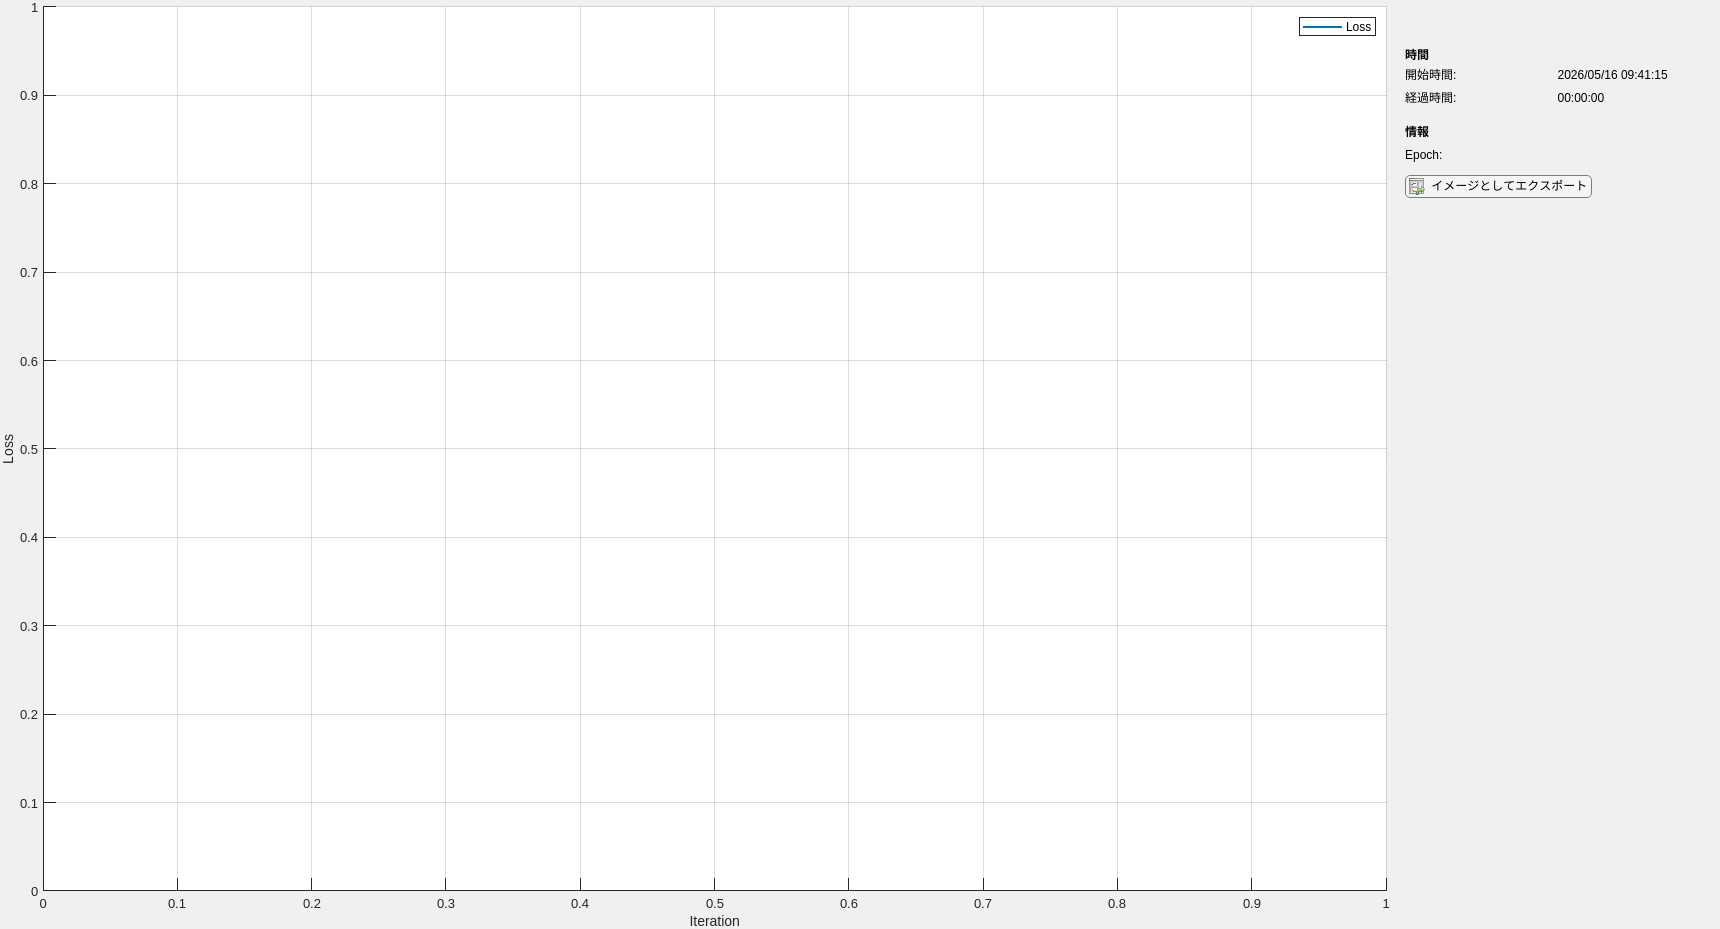

% plot training progress
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");

### forward

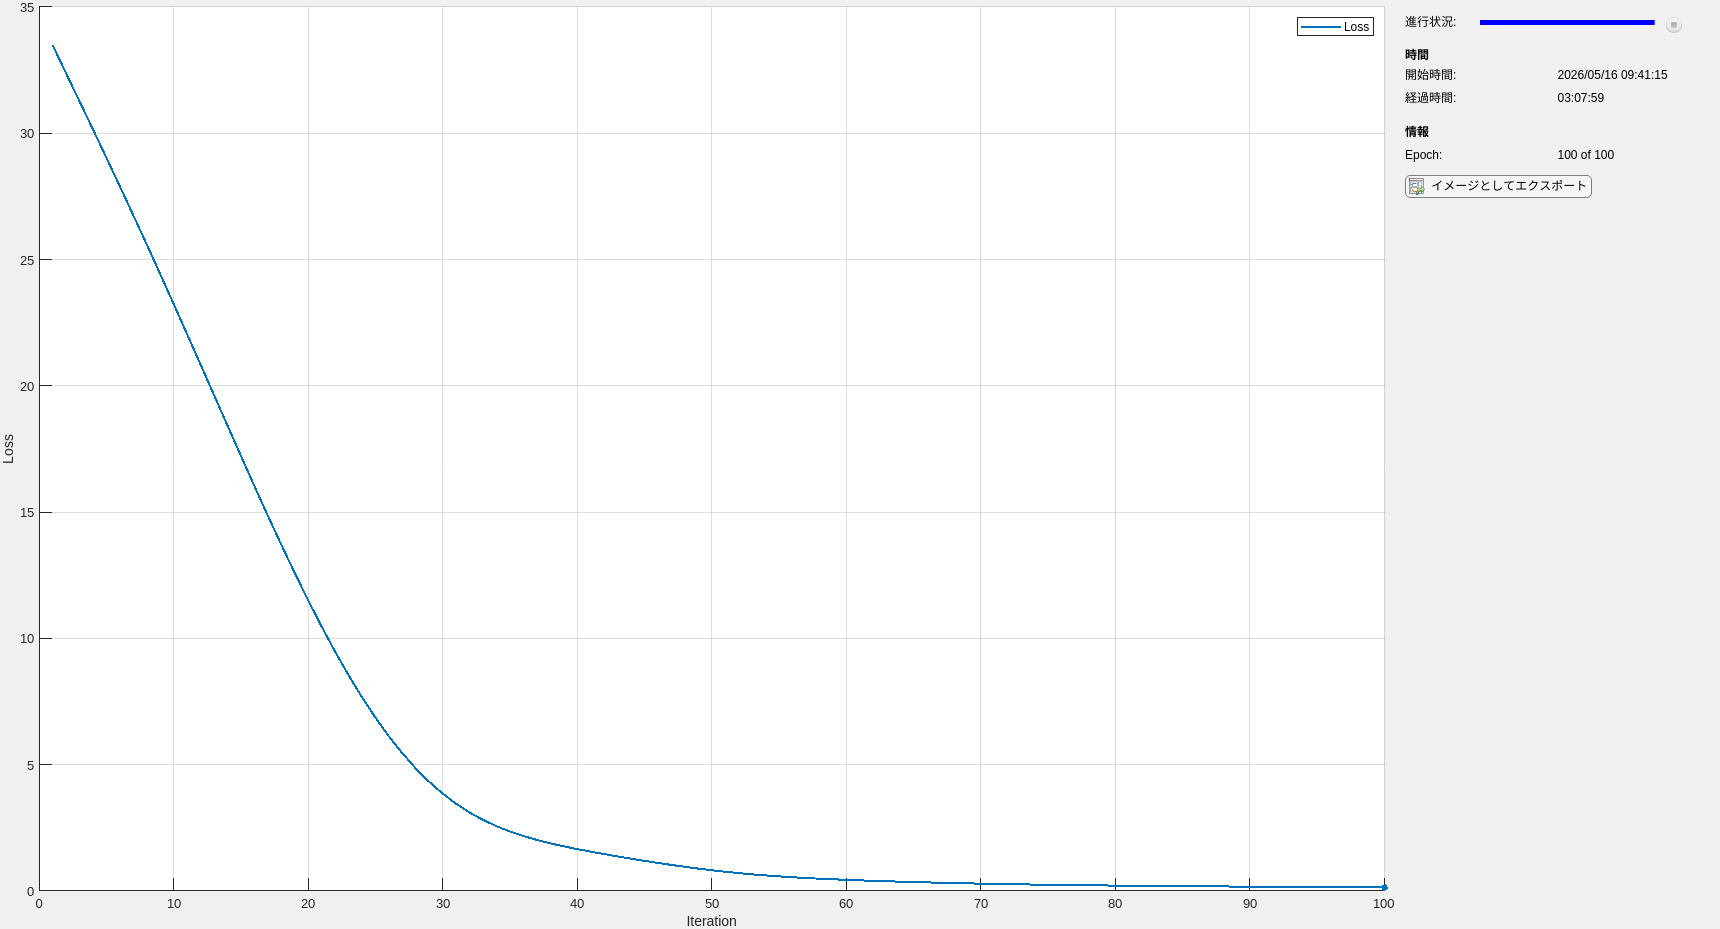

for epoch = 1:maxEpochs

    iteration = iteration + 1;
    
    % DCT
    X_DCT = DCT_2D(u, blksz(1), blksz(2));
    
    % initial rotation
    X_R0 = Rot_initial(X_DCT,anglesWU0);
    
    % right shift + butterfly + rotation
    X_shift_R = atomext_(X_R0,'Right','Difference');
    X_R1 = Rot_inter(X_shift_R,anglesUh1,-1);
    
    % left shift + butterfly + rotation
    X_shift_L = atomext_(X_R1,'Left','Sum');
    X_R2 = Rot_inter(X_shift_L,anglesUh2,1);
    
    % down shift + butterfly + rotation
    X_shift_D = atomext_(X_R2,'Down','Difference');
    X_R3 = Rot_inter(X_shift_D,anglesUv1,-1);
    
    % up shift + butterfly + rotation
    X_shift_U = atomext_(X_R3,'Up','Sum');    
    dlX = Rot_inter(X_shift_U,anglesUv2,1);
    
    % mask
    dlX = coefMask(:).*dlX;
    
    % loss function
    n_loss = sum(squeeze(sum(u.^2,[1,2]))-squeeze(sum(dlX.^2,[1,2,3])),"all")/szt;
    
    % Backward
    dLdLoss = -2.*dlX;

    [dLdX, dLdUv2] = backward_Un(X_shift_U, dLdLoss, anglesUv2,1);
    dLdX = backward_shift(dLdX,'Up','Sum');
    [dLdX, dLdUv1] = backward_Un(X_shift_D, dLdX, anglesUv1,-1);
    dLdX = backward_shift(dLdX,'Down','Difference');
    [dLdX, dLdUh2] = backward_Un(X_shift_L, dLdX, anglesUh2,1);
    dLdX = backward_shift(dLdX,'Left','Sum');
    [dLdX, dLdUh1] = backward_Un(X_shift_R, dLdX, anglesUh1,-1);
    dLdX = backward_shift(dLdX,'Right','Difference');
    [dLdX, dLdWU0] = backward_U0W0(X_DCT, dLdX, anglesWU0);
    dLdX = backward_DCT(dLdX, blksz(1), blksz(2));
    
    % update learnable parameter
    [anglesWU0, AG_WU0, ASG_WU0] = adamupdate(anglesWU0, dLdWU0, AG_WU0, ASG_WU0, iteration,learnRate, B1, B2);
    [anglesUh1, AG_Uh1, ASG_Uh1] = adamupdate(anglesUh1, dLdUh1, AG_Uh1, ASG_Uh1, iteration,learnRate, B1, B2);
    [anglesUh2, AG_Uh2, ASG_Uh2] = adamupdate(anglesUh2, dLdUh2, AG_Uh2, ASG_Uh2, iteration,learnRate, B1, B2);
    [anglesUv1, AG_Uv1, ASG_Uv1] = adamupdate(anglesUv1, dLdUv1, AG_Uv1, ASG_Uv1, iteration,learnRate, B1, B2);
    [anglesUv2, AG_Uv2, ASG_Uv2] = adamupdate(anglesUv2, dLdUv2, AG_Uv2, ASG_Uv2, iteration,learnRate, B1, B2);
    
    recordMetrics(monitor,iteration,Loss=n_loss);
    updateInfo(monitor,Epoch = epoch + " of " + maxEpochs);
    monitor.Progress = 100 * iteration/numIterations;
    loss(iteration,1) = n_loss;

end

## Approximation by LSUN-base linear autoencoder

% Use the existing synthesis layer structure
import tansacnet.lsun.*
lsunlgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',blksz,...
    'OverlappingFactor',[3 3],...
    'NumberOfVanishingMoments','true',...
    'Mode','Synthesizer');

figure
plot(lsunlgraph)
title('Synthesis LSUN')

predict

% Creating Networks and Copying Parameters
net = dlnetwork(lsunlgraph);
u = gather(u);
u_reconstruct = zeros(szy,szx,szt,'like',u);

dlx = cell(1,2);

for iSample = 1:szt
    dlx{1} = dlarray(permute(dlX(2:p,:,:,iSample),[2 3 1 4]),'SSCB');
    dlx{2} = dlarray(permute(dlX(1,:,:,iSample),[2 3 1 4]),'SSCB');
    net.Learnables.Value{1} = dlarray(anglesUv2(:,:,iSample));
    net.Learnables.Value{2} = dlarray(anglesUv1(:,:,iSample));
    net.Learnables.Value{3} = dlarray(anglesUh2(:,:,iSample));
    net.Learnables.Value{4} = dlarray(anglesUh1(:,:,iSample));
    net.Learnables.Value{5} = dlarray(anglesWU0(:,:,iSample));
    u_reconstruct(:,:,iSample) = net.predict(dlx{:});
end

### Performance Evaluation and Save Results

mse = mean((u - u_reconstruct).^2,'all')

mse = single
1.5833e-06

mae = mean(abs(u - u_reconstruct),'all')

mae = single
6.1603e-04


pass = "./Experience1/Result/snapshotLSUN/K_3/";
%% Save WorkSpace
writematrix(mse,pass + "mse.txt");
writematrix(mae,pass + "mae.txt");
writematrix(n_loss,pass + "loss.txt");

save(pass + "u_reconstruct.mat","u_reconstruct");
save(pass + "loss.mat","loss");
save(pass + "anglesWU0.mat","anglesWU0");
save(pass + "anglesUh1.mat","anglesUh1");
save(pass + "anglesUh2.mat","anglesUh2");
save(pass + "anglesUv1.mat","anglesUv1");
save(pass + "anglesUv2.mat","anglesUv2");

### Function of Constructing Analysis LSUN

2-D Block DCT

function X_DCT = DCT_2D(X, decV, decH)
nDec = decV*decH;

nRows = size(X,1)/decV;
nCols = size(X,2)/decH;
nSamples = size(X,3);

Cv_ = dctmtx(decV);
Ch_ = dctmtx(decH);
Cv_ = [ Cv_(1:2:end,:) ; Cv_(2:2:end,:) ];
Ch_ = [ Ch_(1:2:end,:) ; Ch_(2:2:end,:) ];

Cve = Cv_(1:ceil(decV/2),:);
Cvo = Cv_(ceil(decV/2)+1:end,:);
Che = Ch_(1:ceil(decH/2),:);
Cho = Ch_(ceil(decH/2)+1:end,:);
Cee = kron(Che,Cve);
Coo = kron(Cho,Cvo);
Coe = kron(Che,Cvo);
Ceo = kron(Cho,Cve);
Cvh = [Cee; Coo; Coe; Ceo];
arrayX = permute(reshape(X, decV,nRows,decH,nCols,nSamples),[1 3 2 4 5]);
if isgpuarray(X)
    X_DCT = pagefun(@mtimes,Cvh,...
        reshape(arrayX,nDec,nRows,nCols,nSamples));
else
    X_DCT = reshape(Cvh*reshape(arrayX,nDec,[]),nDec,nRows,nCols,nSamples);
end
end

Initial Rotation

function X_Rot_ini = Rot_initial(X,angles)
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = ones(ps+pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
muW = mus(1:ps,:,:);        % Revised
muU = mus(ps+1:end,:,:);        % Revised

angles(1:ps-1,:,:) = zeros(ps-1,nrows*ncols,nSamples,'like',angles);       % Revised

anglesW = angles(1:size(angles,1)/2,:,:);       % Revised
anglesU = angles(size(angles,1)/2+1:end,:,:);   % Revised

W0_ = fcn_orthmtxgen(anglesW,muW);
U0_ = fcn_orthmtxgen(anglesU,muU);

Y = reshape(X,ps+pa,nrows*ncols,nSamples);
Zs = zeros(ps,nrows*ncols,nSamples,'like',Y);
Za = zeros(pa,nrows*ncols,nSamples,'like',Y);

for iSample = 1:nSamples
    if isgpuarray(X)
        Ys_iSample = permute(Y(1:ps,:,iSample),[1 4 2 3]);
        Ya_iSample = permute(Y(ps+1:end,:,iSample),[1 4 2 3]);
        Zs_iSample = pagefun(@mtimes,W0_(:,:,:,iSample),Ys_iSample);        % Revised
        Za_iSample = pagefun(@mtimes,U0_(:,:,:,iSample),Ya_iSample);        % Revised
        Zs(:,:,iSample) = ipermute(Zs_iSample,[1 4 2 3]);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Zs(:,iblk,iSample) = W0_(:,1:ps,iblk,iSample)*Y(1:ps,iblk,iSample);
            Za(:,iblk,iSample) = U0_(:,1:pa,iblk,iSample)*Y(ps+1:end,iblk,iSample);
        end
    end
end

X_Rot_ini = reshape([Zs;Za],ps+pa,nrows,ncols,nSamples);

end

Shift & Butterfly Operation

function X_shift = atomext_(X,dir,target)
ps = size(X,1)/2;
pa = ps;

% Block Butterfly Operation
Xs = X(1:ps,:,:,:);
Xa = X(ps+1:ps+pa,:,:,:);
Ys =  bsxfun(@plus,Xs,Xa);
Ya =  bsxfun(@minus,Xs,Xa);

% Shift operation
if strcmp(dir,'Right')
    shift = [ 0 0 1 0];
elseif strcmp(dir,'Left')
    shift = [ 0 0 -1 0];
elseif strcmp(dir,'Down')
    shift = [ 0 1 0 0];
elseif strcmp(dir,'Up')
    shift = [ 0 -1 0 0];
else
    throw(MException('NsoltLayer:InvalidDirection',...
        '%s : Direction should be either of Right, Left, Down or Up',...
        layer.Direction))
end
if strcmp(target,'Difference')
    Ya = circshift(Ya,shift);
elseif strcmp(target,'Sum')
    Ys = circshift(Ys,shift);
else
    throw(MException('NsoltLayer:InvalidTargetChannels',...
        '%s : TaregetChannels should be either of Sum or Difference',...
        layer.TargetChannels))
end

% Block Butterfly Operation
Y =  cat(1,bsxfun(@plus,Ys,Ya),bsxfun(@minus,Ys,Ya));

X_shift = 0.5*Y;
end

Intermadiate Rotation

function X_Rot_int = Rot_inter(X,angles,Mus)

nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = Mus*ones(pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
Un_ = fcn_orthmtxgen(angles,mus);

Y = X;
Ya = reshape(Y(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
A_ = Un_;

Za = zeros(pa,nrows*ncols,nSamples,'like',Y);
for iSample = 1:nSamples
    if isgpuarray(X)
        Ya_iSample = permute(Ya(:,:,iSample),[1 4 2 3]);
        Za_iSample = pagefun(@mtimes,A_(:,:,:,iSample),Ya_iSample);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Za(:,iblk,iSample) = A_(:,:,iblk,iSample)*Ya(:,iblk,iSample);
        end
    end
end
Y(ps+1:ps+pa,:,:,:) = reshape(Za,pa,nrows,ncols,nSamples);
X_Rot_int = Y;
end

Generation of Rotation Matrices

function matrix = fcn_orthmtxgen(angles,mus)                % Revised
useGpu = isgpuarray(angles);
nDim_ = (1+sqrt(1+8*size(angles,1)))/2;
nMatrices_ = size(angles,2);
nSamples = size(angles,3);      % Revised
matrix = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);        % Revised
if useGpu
    if ~isempty(angles)
        %for iMtx = 1:nMatrices_
        iAng = uint32(1);
        for iTop=1:nDim_-1
            vt = matrix(iTop,:,:,:);      % Revised
            for iBtm=iTop+1:nDim_
                angle = permute(angles(iAng,:,:),[1 4 2 3]);      % Revised
                %
                c = cos(angle);
                s = sin(angle);
                vb = matrix(iBtm,:,:,:);        % Revised
                %
                u = pagefun(@times,s,bsxfun(@plus,vt,vb));
                vt = bsxfun(@minus,pagefun(@times,bsxfun(@plus,c,s),vt),u);
                matrix(iBtm,:,:,:) = bsxfun(@plus,pagefun(@times,bsxfun(@minus,c,s),vb),u);     % Revised
                %u  = arrayfun(@(s,vt,vb) s.*(vt+vb),s,vt,vb);
                %vt = arrayfun(@(c,s,vt,u) (c+s).*vt-u,c,s,vt,u);
                %matrix(iBtm,:,:) = arrayfun(@(c,s,vb,u) (c-s).*vb+u,c,s,vb,u);
                %
                iAng = iAng + 1;
            end
            matrix(iTop,:,:,:) = vt;        % Revised
        end
        %end
    end
    if isvector(mus) || isscalar(mus)
        matrix = pagefun(@times,permute(mus(:),[1 4 3 2]),matrix);      % Revised
    else
        matrix = pagefun(@times,permute(mus,[1 4 2 3]),matrix);     % Revised
    end
else
    if ~isempty(angles)
        for iSample = 1:nSamples        % Revised
            for iMtx = 1:nMatrices_
                iAng = uint32(1);
                for iTop=1:nDim_-1
                    vt = matrix(iTop,:,iMtx,iSample);       % Revised
                    for iBtm=iTop+1:nDim_
                        angle = angles(iAng,iMtx,iSample);      % Revised
                        if angle ~= 0
                            c = cos(angle);
                            s = sin(angle);
                            vb = matrix(iBtm,:,iMtx,iSample);       % Revised
                            
                            u  = s.*(vt+vb);
                            vt = (c+s).*vt-u;
                            matrix(iBtm,:,iMtx,iSample) = (c-s).*vb+u;      % Revised
                            
                        end
                        %
                        iAng = iAng + 1;
                    end
                    matrix(iTop,:,iMtx,iSample) = vt;       % Revised
                end
            end
        end
    end
    for iSample = 1:nSamples        % Revised
        for iMtx = 1:nMatrices_
            if isvector(mus) || isscalar(mus)
                matrix(:,:,iMtx,iSample) = mus(:).*matrix(:,:,iMtx,iSample);        % Revised
            else
                matrix(:,:,iMtx,iSample) = mus(:,iMtx,iSample).*matrix(:,:,iMtx,iSample);       % Revised
            end
        end
    end
end
end

**Backpropagation Function**

2-D DCT

function dLdX = backward_DCT(dLdZ, decV, decH)

nDec = decV*decH;

Cv_ = dctmtx(decV);
Ch_ = dctmtx(decH);
Cv_ = [ Cv_(1:2:end,:) ; Cv_(2:2:end,:) ];
Ch_ = [ Ch_(1:2:end,:) ; Ch_(2:2:end,:) ];
%
Cve = Cv_(1:ceil(decV/2),:);
Cvo = Cv_(ceil(decV/2)+1:end,:);
Che = Ch_(1:ceil(decH/2),:);
Cho = Ch_(ceil(decH/2)+1:end,:);
Cee = kron(Che,Cve);
Coo = kron(Cho,Cvo);
Coe = kron(Che,Cvo);
Ceo = kron(Cho,Cve);
Cvh_T = [Cee; Coo; Coe; Ceo].';
%
nRows = size(dLdZ,2);
nCols = size(dLdZ,3);
height = decV*nRows;
width = decH*nCols;
nSamples = size(dLdZ,4);
%
if isgpuarray(dLdZ)
    arrayX = pagefun(@mtimes,Cvh_T,dLdZ);
else
    arrayX = Cvh_T*reshape(dLdZ,nDec,[]);
end

dLdX = reshape(ipermute(reshape(arrayX,decV,decH,nRows,nCols,nSamples),[1 3 2 4 5]),height,width,nSamples);
end

Initial Rotation

function [dLdX, dLdW] = backward_U0W0(X, dLdZ, angles0)

nrows = size(dLdZ,2);
ncols = size(dLdZ,3);
nSamples = size(dLdZ,4);
ps = size(dLdZ,1)/2;
pa = ps;

nAngles = size(angles0,1);
mus = ones(ps+pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles0);
muW = mus(1:ps,:,:);        % Revised
muU = mus(ps+1:end,:,:);    % Revised
anglesW = angles0(1:nAngles/2,:,:);     % Revised
anglesU = angles0(nAngles/2+1:end,:,:); % Revised

W0_ = fcn_orthmtxgen(anglesW,muW);
U0_ = fcn_orthmtxgen(anglesU,muU);
W0T = permute(W0_,[2 1 3 4]);       % Revised
U0T = permute(U0_,[2 1 3 4]);       % Revised
% dW0Pst = zeros(size(W0_),'like',W0_);
% dU0Pst = zeros(size(U0_),'like',U0_);

dW0Pst = bsxfun(@times,permute(muW,[1 4 2 3]),W0_);        % Revised
dU0Pst = bsxfun(@times,permute(muU,[1 4 2 3]),U0_);        % Revised

dW0Pre = repmat(eye(ps,'like',W0_),[1 1 (nrows*ncols) nSamples]);
dU0Pre = repmat(eye(pa,'like',U0_),[1 1 (nrows*ncols) nSamples]);

% Layer backward function goes here.
% dLdX = dZdX x dLdZ
Ys = reshape(dLdZ(1:ps,:,:,:),ps,nrows*ncols,nSamples);
Ya = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iSample = 1:nSamples
    if isgpuarray(X)
        Ys_iSample = permute(Ys(:,:,iSample),[1 4 2 3]);
        Ya_iSample = permute(Ya(:,:,iSample),[1 4 2 3]);
        Ys_iSample = pagefun(@mtimes,W0T(1:ps,:,:,iSample),Ys_iSample);
        Ya_iSample = pagefun(@mtimes,U0T(1:pa,:,:,iSample),Ya_iSample);
        Ys(:,:,iSample) = ipermute(Ys_iSample,[1 4 2 3]);
        Ya(:,:,iSample) = ipermute(Ya_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Ys(:,iblk,iSample) = W0T(1:ps,:,iblk,iSample)*Ys(:,iblk,iSample);
            Ya(:,iblk,iSample) = U0T(1:pa,:,iblk,iSample)*Ya(:,iblk,iSample);
        end
    end
end
Zsa = cat(1,Ys,Ya);
dLdX = reshape(Zsa,ps+pa,nrows,ncols,nSamples);

% dLdWi = <dLdZ,(dVdWi)X>
dLdW = zeros(nAngles,nrows*ncols,nSamples,'like',dLdZ);                                 % revised
dldz_upp = reshape(dLdZ(1:ps,:,:,:),ps,nrows*ncols,nSamples);
dldz_low = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
% (dVdWi)X
c_upp = reshape(X(1:ps,:,:,:),ps,nrows*ncols,nSamples);
c_low = reshape(X(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iAngle = uint32(1:nAngles/2)
    
    [dW0,dW0Pst,dW0Pre] = fcn_orthmtxgen_diff(anglesW,muW,iAngle,dW0Pst,dW0Pre);
    [dU0,dU0Pst,dU0Pre] = fcn_orthmtxgen_diff(anglesU,muU,iAngle,dU0Pst,dU0Pre);
    if isgpuarray(X)
        c_upp_ext = permute(c_upp,[1 4 2 3]); % idx 1 iblk iSample
        c_low_ext = permute(c_low,[1 4 2 3]); % idx 1 iblk iSample
        d_upp_ext = pagefun(@mtimes,dW0(:,1:ps,:,:),c_upp_ext); % idx 1 iblk iSample
        d_low_ext = pagefun(@mtimes,dU0(:,1:pa,:,:),c_low_ext); % idx 1 iblk iSample                    
        d_upp = ipermute(d_upp_ext,[1 4 2 3]);
        d_low = ipermute(d_low_ext,[1 4 2 3]);                    
        dLdW(iAngle,:,:) = sum(bsxfun(@times,dldz_upp,d_upp),1);                          % revised
        dLdW(nAngles/2+iAngle,:,:) = sum(bsxfun(@times,dldz_low,d_low),1);                % revised    
    else
        for iblk = 1:(nrows*ncols)
            dldz_upp_iblk = squeeze(dldz_upp(:,iblk,:));
            dldz_low_iblk = squeeze(dldz_low(:,iblk,:));
            c_upp_iblk = squeeze(c_upp(:,iblk,:));
            c_low_iblk = squeeze(c_low(:,iblk,:));
            d_upp_iblk = zeros(size(c_upp_iblk),'like',c_upp_iblk);
            d_low_iblk = zeros(size(c_low_iblk),'like',c_low_iblk);
            for iSample = 1:nSamples
                d_upp_iblk(:,iSample) = dW0(:,1:ps,iblk)*c_upp_iblk(:,iSample);
                d_low_iblk(:,iSample) = dU0(:,1:pa,iblk)*c_low_iblk(:,iSample);
            end
            dLdW(iAngle,iblk,:) = sum(bsxfun(@times,dldz_upp_iblk,d_upp_iblk),1);            % revised
            dLdW(nAngles/2+iAngle,iblk,:) = sum(bsxfun(@times,dldz_low_iblk,d_low_iblk),1);  % revised
        end
    end
end
end

Shift & Butterfly Operation

function dLdX = backward_shift(dLdZ,dir,target)

ps = size(dLdZ,1)/2;
pa = ps;

% Block Butterfly Operation
Xs = dLdZ(1:ps,:,:,:);
Xa = dLdZ(ps+1:ps+pa,:,:,:);
Ys =  bsxfun(@plus,Xs,Xa);
Ya =  bsxfun(@minus,Xs,Xa);

if strcmp(dir,'Right')
    shift = [ 0 0 -1 0];  % Reverse
elseif strcmp(dir,'Left')
    shift = [ 0 0 1 0];  % Reverse
elseif strcmp(dir,'Down')
    shift = [ 0 -1 0 0];  % Reverse
elseif strcmp(dir,'Up')
    shift = [ 0 1 0 0];  % Reverse
else
    throw(MException('NsoltLayer:InvalidDirection',...
        '%s : Direction should be either of Right, Left, Down or Up',...
        layer.Direction))
end

if strcmp(target,'Difference')
    Ya = circshift(Ya,shift);
elseif strcmp(target,'Sum')
    Ys = circshift(Ys,shift);
else
    throw(MException('NsoltLayer:InvalidTargetChannels',...
        '%s : TaregetChannels should be either of Sum or Difference',...
        layer.TargetChannels))
end

% Block Butterfly Operation
Y =  cat(1,bsxfun(@plus,Ys,Ya),bsxfun(@minus,Ys,Ya));

dLdX = 0.5*Y;
end

Intermadiate Rotation

function [dLdX, dLdW] = backward_Un(X, dLdZ, anglesU, Mus)

nrows = size(dLdZ,2);
ncols = size(dLdZ,3);
nSamples = size(dLdZ,4);
ps = size(dLdZ,1)/2;
pa = ps;

mus = Mus*ones(pa,nrows*ncols,nSamples);
musU = cast(mus,'like',anglesU);

Un_ = fcn_orthmtxgen(anglesU,musU);

dUnPst = bsxfun(@times,permute(musU,[1 4 2 3]),Un_);
dUnPre = repmat(eye(pa,'like',Un_),[1 1 (nrows*ncols) nSamples]);

dLdX = reshape(dLdZ,ps+pa,nrows,ncols,nSamples);                         % Gradient from Next Layer

UnT = permute(Un_,[2 1 3 4]);                                      % U^T

cdLd_low = reshape(dLdX(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iSample = 1:nSamples
    if isgpuarray(X)
        cdLd_low_iSample = permute(cdLd_low(:,:,iSample),[1 4 2 3]);
        cdLd_low_iSample = pagefun(@mtimes,UnT(:,:,:,iSample),cdLd_low_iSample);
        cdLd_low(:,:,iSample) = ipermute(cdLd_low_iSample,[1 4 2 3]);                    
    else
        for iblk = 1:(nrows*ncols)
            cdLd_low(:,iblk,iSample) = UnT(:,:,iblk,iSample)*cdLd_low(:,iblk,iSample);
        end
    end
end

dLdX(ps+1:ps+pa,:,:,:) = reshape(cdLd_low,pa,nrows,ncols,nSamples);


nAngles = size(anglesU,1);
dLdW = zeros(nAngles,nrows*ncols,nSamples,'like',dLdZ);                             % revised
dldz_low = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
c_low = reshape(X(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);

for iAngle = uint32(1:nAngles)
    [dUn,dUnPst,dUnPre] = fcn_orthmtxgen_diff(anglesU,musU,iAngle,dUnPst,dUnPre);
    
    dA_ = dUn;
    if isgpuarray(X)
        c_low_ext = permute(c_low,[1 4 2 3]); % idx 1 iblk iSample
        d_low_ext = pagefun(@mtimes,dA_,c_low_ext); % idx 1 iblk iSample
        d_low = ipermute(d_low_ext,[1 4 2 3]);
        dLdW(iAngle,:,:) = sum(bsxfun(@times,dldz_low,d_low),1);                             % revised
    else
        for iblk = 1:(nrows*ncols)
            dA_iblk = dA_(:,:,iblk);
            dldz_low_iblk = squeeze(dldz_low(:,iblk,:));
            c_low_iblk = squeeze(c_low(:,iblk,:));
            d_low_iblk = zeros(size(c_low_iblk),'like',c_low_iblk);
            for iSample = 1:nSamples
                d_low_iblk(:,iSample) = dA_iblk*c_low_iblk(:,iSample);
            end
            dLdW(iAngle,iblk,:) = sum(bsxfun(@times,dldz_low_iblk,d_low_iblk),1);            % revised
        end
    end
end
end

Differential Generation of Rotation Matrices

function [matrix,matrixpst,matrixpre] = fcn_orthmtxgen_diff(angles,mus,pdAng,matrixpst,matrixpre)
useGpu = isgpuarray(angles);
nDim_ = (1+sqrt(1+8.*size(angles,1)))/2;
nMatrices_ = size(angles,2);
nSamples = size(angles,3);
matrix = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);
if useGpu
    %for iMtx = 1:nMatrices_
    matrixrev = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);
    matrixdif = zeros(nDim_,nDim_,nMatrices_,nSamples,'like',angles);
    iAng = uint32(1);
    for iTop=1:nDim_-1
        rt = matrixrev(iTop,:,:,:);
        dt = zeros(1,nDim_,nMatrices_,nSamples,'like',angles);
        dt(1,iTop,:,:) = 1;
        for iBtm=iTop+1:nDim_
            if iAng == pdAng
                angle = angles(iAng,:,:);
                %
                rb = matrixrev(iBtm,:,:,:);
                db = zeros(1,nDim_,nMatrices_,nSamples,'like',angles);
                db(1,iBtm,:,:) = 1;
                dangle = angle + pi/2;
                %
                %[rt,rb] = rot_(rt,rb,-angle);
                %[dt,db] = rot_(dt,db,dangle);
                %[vt,vb] = rot_([rt;dt],[rb;db],[-angle;dangle],...
                %    useGpu,isLessThanR2021b);
                vt = [rt;dt];
                vb = [rb;db];
                angle_ = permute([-angle;dangle],[1 4 2 3]);
                c = cos(angle_);
                s = sin(angle_);
                %u  = arrayfun(@(s,vt,vb) s.*(vt+vb),s,vt,vb);
                %vt = arrayfun(@(c,s,vt,u) (c+s).*vt-u,c,s,vt,u);
                %vb = arrayfun(@(c,s,vb,u) (c-s).*vb+u,c,s,vb,u);
                u  = pagefun(@times,s,bsxfun(@plus,vt,vb));
                vt = bsxfun(@minus,pagefun(@times,bsxfun(@plus,c,s),vt),u);
                vb = bsxfun(@plus,pagefun(@times,bsxfun(@minus,c,s),vb),u);
                %
                matrixrev(iTop,:,:,:) = vt(1,:,:,:); %rt;
                matrixrev(iBtm,:,:,:) = vb(1,:,:,:); %rb;
                matrixdif(iTop,:,:,:) = vt(2,:,:,:); %dt;
                matrixdif(iBtm,:,:,:) = vb(2,:,:,:); %db;
                %
                matrixpst = pagefun(@mtimes,matrixpst,matrixrev);
                matrix = pagefun(@mtimes,pagefun(@mtimes,matrixpst,matrixdif),matrixpre);
                matrixpre = pagefun(@mtimes,pagefun(@transpose,matrixrev),matrixpre);
            end
            iAng = iAng + 1;
        end
    end
    %end
    if isvector(mus) || isscalar(mus)
        matrix = pagefun(@times,mus(:),matrix);
    else
        matrix = pagefun(@times,permute(mus,[1 4 2 3]),matrix);
    end
else
    for iMtx = 1:nMatrices_
        matrixrev = eye(nDim_,'like',angles);
        matrixdif = zeros(nDim_,'like',angles);
        iAng = uint32(1);
        for iTop=1:nDim_-1
            rt = matrixrev(iTop,:);
            dt = zeros(1,nDim_,'like',angles);
            dt(iTop) = 1;
            for iBtm=iTop+1:nDim_
                if iAng == pdAng
                    angle = angles(iAng,iMtx);
                    %
                    rb = matrixrev(iBtm,:);
                    db = zeros(1,nDim_,'like',angles);
                    db(iBtm) = 1;
                    dangle = angle + pi/2;
                    %
                    %[rt,rb] = rot_(rt,rb,-angle);
                    %[dt,db] = rot_(dt,db,dangle);
                    [vt,vb] = rot_([rt;dt],[rb;db],[-angle;dangle]);
                    %
                    matrixrev(iTop,:) = vt(1,:); %rt;
                    matrixrev(iBtm,:) = vb(1,:); %rb;
                    matrixdif(iTop,:) = vt(2,:); %dt;
                    matrixdif(iBtm,:) = vb(2,:); %db;
                    %
                    matrixpst(:,:,iMtx) = matrixpst(:,:,iMtx)*matrixrev;
                    matrix(:,:,iMtx) = matrixpst(:,:,iMtx)*matrixdif*matrixpre(:,:,iMtx);
                    matrixpre(:,:,iMtx) = matrixrev.'*matrixpre(:,:,iMtx);
                end
                iAng = iAng + 1;
            end
        end
        if isvector(mus) || isscalar(mus)
            matrix(:,:,iMtx) = mus(:).*matrix(:,:,iMtx);
        else
            matrix(:,:,iMtx) = mus(:,iMtx).*matrix(:,:,iMtx);
        end
    end
end
end

rotation function

function [vt,vb] = rot_(vt,vb,angle)
c = cos(angle);
s = sin(angle);
u  = s.*(vt+vb);
vt = (c+s).*vt-u;
vb = (c-s).*vb+u;
end